# C-start data analysis

Demonstrates some of the sample functions.

First load the sample data set.

load("CStart-sample.mat")

Plot it to make sure it makes sense.

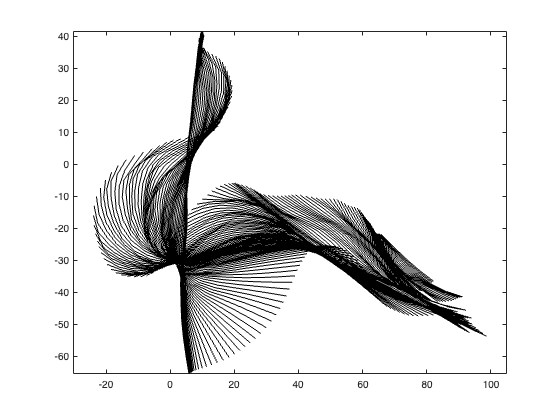

clf;
plot(mxmm, mymm, 'k-');
axis equal;

## Body width and height

We need the width and height of the body to estimate the center of mass, assuming that the body is constant density.

load("bluegillshape.mat");

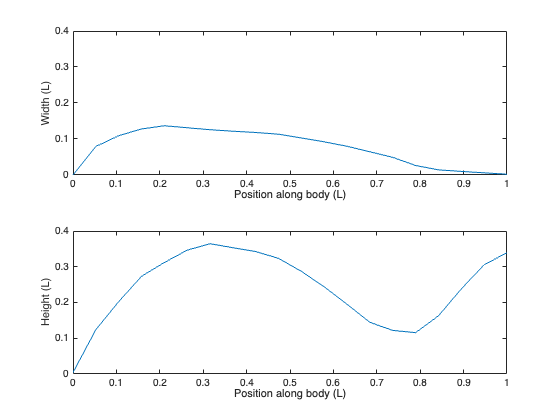

clf;

s0 = linspace(0, 1, length(width));
h(1) = subplot(2,1,1);
plot(s0, width);
xlabel('Position along body (L)');
ylabel('Width (L)');

h(2) = subplot(2,1,2);
plot(s0, height);
xlabel('Position along body (L)');
ylabel('Height (L)');

linkaxes(h, 'xy');

## Get stretched straight COM

We can use the width and height to estimate the stretched-straight location of COM (if we haven't measured it from a real animal).

comdist = get_stretched_straight_com(width, height)

comdist = 0.3685

This is the distance (in L) from the tip of the snout to the COM.

True stretched-straight COM for bluegill is 0.442+-0.008 L (Fath 2022), so we're not too far off.

Now interpolate the location of this position on the curved body midline. Note that we have to multiply `comdist` by the body length.

[comx_ss, comy_ss] = interp_stretched_straight_com(mxmm,mymm, ...
    comdist * fishlenmm);

## Get the COM from volume

If the body is constant density, then we can estimate the location of COM from the body shape and the midline.

[comx_vol, comy_vol] = get_com(mxmm, mymm, ...
    "height",height, "width",width);

## Get the COM from just the horizontal area

We can even do a fairly good job estimating the COM from the horizontal area, the area of the body we see from a camera above or below the test section.

[comx_area, comy_area] = get_com(mxmm, mymm, "width", width);

# Compare the path of the different COM estimates

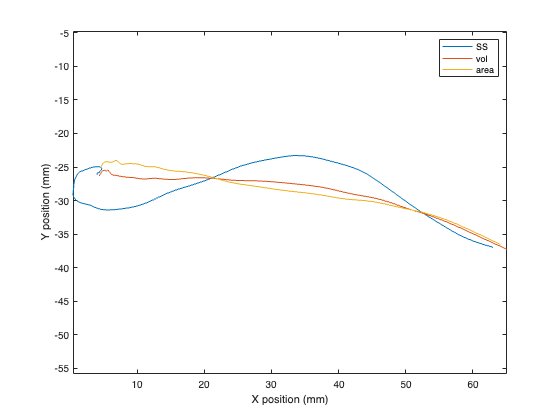

clf;
plot(comx_ss, comy_ss, ...
    comx_vol, comy_vol, ...
    comx_area, comy_area);
axis equal;
legend('SS', 'vol', 'area');

xlabel('X position (mm)');
ylabel('Y position (mm)');

# Smooth the data

To estimate a velocity we nearly always want to smooth our data before estimating a derivative.

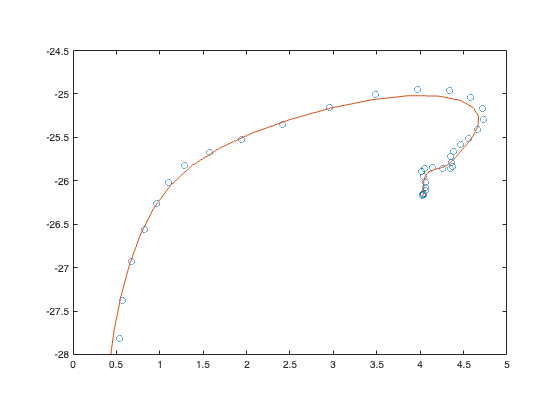

[comx_ss_sm, comy_ss_sm] = smooth_position(tsec, comx_ss, comy_ss, 0.5/5.5);

clf;
plot(comx_ss, comy_ss, 'o',comx_ss_sm,comy_ss_sm,'-');
axis equal;
axis([0 5 -28 -24.5]); % zoom in to the beginning to see the smoothing

We can also smooth the entire midline all at once.

[mxs, mys] = smooth_midline(tsec, mxmm, mymm, fishlenmm, "serr", 0.5/5.5, "terr", 0.5/5.5);

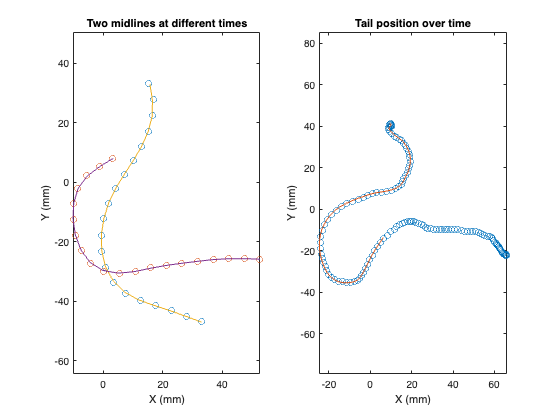

clf;

subplot(1,2,1);

fr = [40 60];
plot(mxmm(:,fr),mymm(:,fr), 'o', ...
    mxs(:,fr),mys(:,fr));
axis equal;
title('Two midlines at different times');
xlabel('X (mm)');
ylabel('Y (mm)');

subplot(1,2,2);
plot(mxmm(end,:),mymm(end,:), 'o', ...
    mxs(end,:),mys(end,:),'-');
xlabel('X (mm)');
ylabel('Y (mm)');
axis equal;
title('Tail position over time');

# Get derivatives

Smooth the other COM estimates and take derivatives

[comx_vol_sm, comy_vol_sm] = smooth_position(tsec, comx_vol, comy_vol, 0.5/5.5);
[comx_area_sm, comy_area_sm] = smooth_position(tsec, comx_area, comy_area, 0.5/5.5);

For comparison, let's take the derivative of the unsmoothed data also.

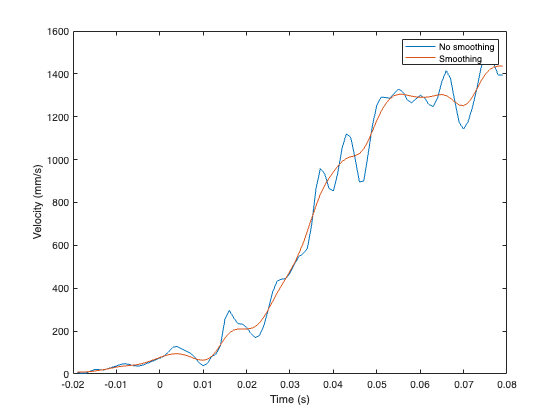

dcomx_vol_bad = deriv(tsec, comx_vol);
dcomy_vol_bad = deriv(tsec, comy_vol);
comvel_vol_bad = sqrt(dcomx_vol_bad.^2 + dcomy_vol_bad.^2);

dcomx_vol = deriv(tsec, comx_vol_sm);
dcomy_vol = deriv(tsec, comy_vol_sm);
comvel_vol = sqrt(dcomx_vol.^2 + dcomy_vol.^2);

clf;
plot(tsec, comvel_vol_bad, ...
    tsec, comvel_vol);
legend('No smoothing', 'Smoothing');
xlabel('Time (s)');
ylabel('Velocity (mm/s)');

## Compare the different COM estimates

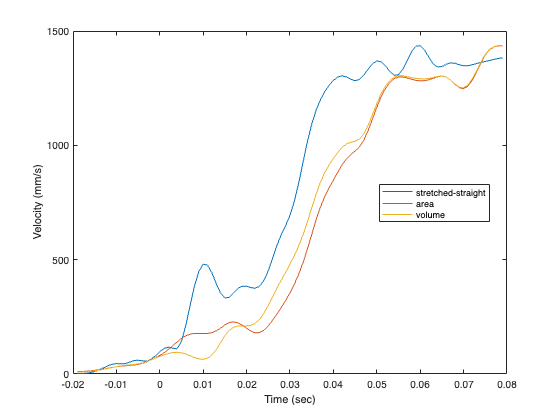

dcomx_area = deriv(tsec, comx_area_sm);
dcomy_area = deriv(tsec, comy_area_sm);
comvel_area = sqrt(dcomx_area.^2 + dcomy_area.^2);

dcomx_ss = deriv(tsec, comx_ss_sm);
dcomy_ss = deriv(tsec, comy_ss_sm);
comvel_ss = sqrt(dcomx_ss.^2 + dcomy_ss.^2);

clf;
plot(tsec, comvel_ss, ...
    tsec, comvel_area, ...
    tsec, comvel_vol);
legend('stretched-straight', 'area', 'volume', 'Location','best');
xlabel('Time (sec)');
ylabel('Velocity (mm/s)');